# Live Script of Data Plots for Lab 3

% This is a live script that will be used to plot the data that was
% collected in the 0.5 seconds of ADC samples taken and then passed through
% the filters created
% 
% Samuel Kramer
% March 9, 2022
%

% -- Setup 
clc; format compact; close all;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Plot 1 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

N = length(data);
ts = 1/1000;
t = ts*[0:N-1];
Voltage1 = data(:,1);
NotchOutput = data(:,2);
NotchVoltage = 10.^(NotchOutput./20); % convert from dB to voltage

% Create plot of t and Voltage1
h = plot(t,Voltage1,'DisplayName','Voltage1');

% Add xlabel, ylabel, title, and legend
xlabel('t')
ylabel('Voltage1')
title('t vs. Voltage1')
legend
hold on;

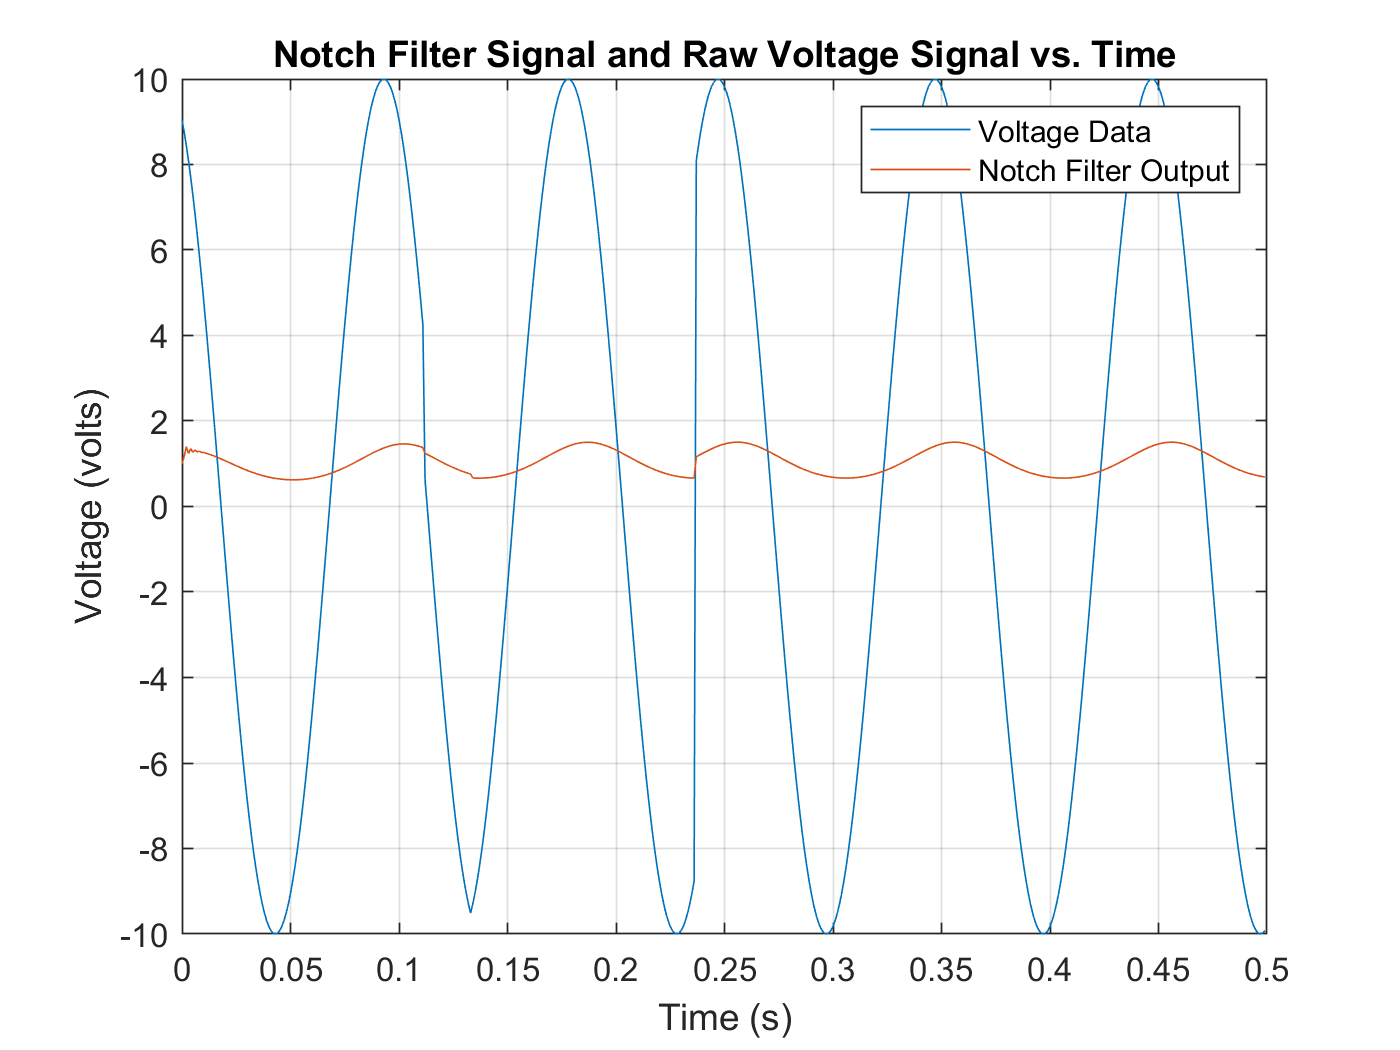

% Create plot of t and NotchVoltage
h2 = plot(t,NotchVoltage,'DisplayName','NotchVoltage');

% Add xlabel, ylabel, title, and legend
xlabel('t')
ylabel('NotchVoltage')
title('t vs. NotchVoltage')
legend
hold on;
title('Notch Filter Signal and Raw Voltage Signal vs. Time');
xlabel('Time (s)');
ylabel('Voltage (volts)');
legend('Voltage Data','Notch Filter Output')
grid on;


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Plot 2 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure
Voltage2 = data(:,3);
ButterOutput = data(:,4);
ButterVoltage = 10.^(ButterOutput./20); % convert from dB to voltage

% Create plot of t and Voltage2
h3 = plot(t,Voltage2,'DisplayName','Voltage2');

% Add xlabel, ylabel, title, and legend
xlabel('t')
ylabel('Voltage2')
title('t vs. Voltage2')
legend
hold on;

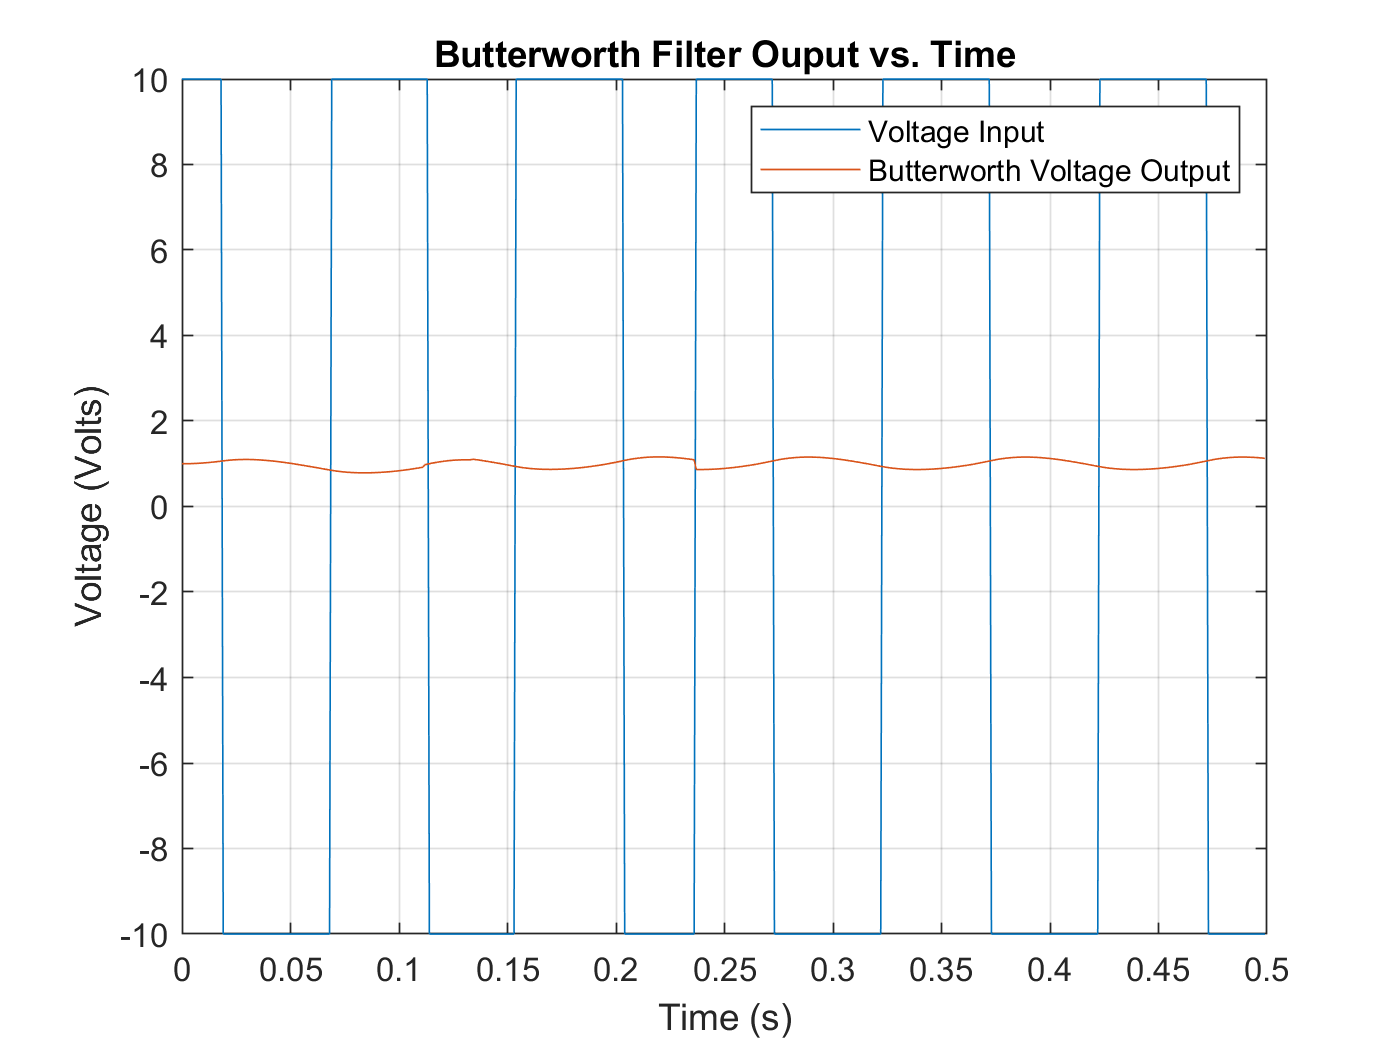

% Create plot of t and ButterVoltage
h4 = plot(t,ButterVoltage,'DisplayName','ButterVoltage');

% Add xlabel, ylabel, title, and legend
xlabel('t')
ylabel('ButterVoltage')
title('t vs. ButterVoltage')
legend
hold on;
xlabel('Time (s)')
ylabel('Voltage (Volts)')
title('Butterworth Filter Ouput vs. Time')
grid on
legend('Voltage Input','Butterworth Voltage Output')